raw_data = readtable('lab_2_part_2.csv'); 

time_vals = rmmissing(raw_data.Time_s_0_2SameAngle);
angle_vals = rmmissing(raw_data.Angle_ChP1_rad_0_2SameAngle);
angle_vals_minus_mean = (angle_vals - mean(angle_vals));
angle_vals_minus_mean = angle_vals_minus_mean ./ max(angle_vals_minus_mean);
plot(time_vals, angle_vals_minus_mean,':', "Color", "green")
hold on 
% fplot(@(x) 0.1*sin(0.32*x - 1.2) - 0.2, [min(time_vals), max(time_vals)])
% fplot(@(x) 0.1*sin(4.01*x - 1.2) + 0.2, [min(time_vals), max(time_vals)])
hold off
ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
xlim([min(time_vals), max(time_vals)])
legend("Angle from experiment", "TSlow")

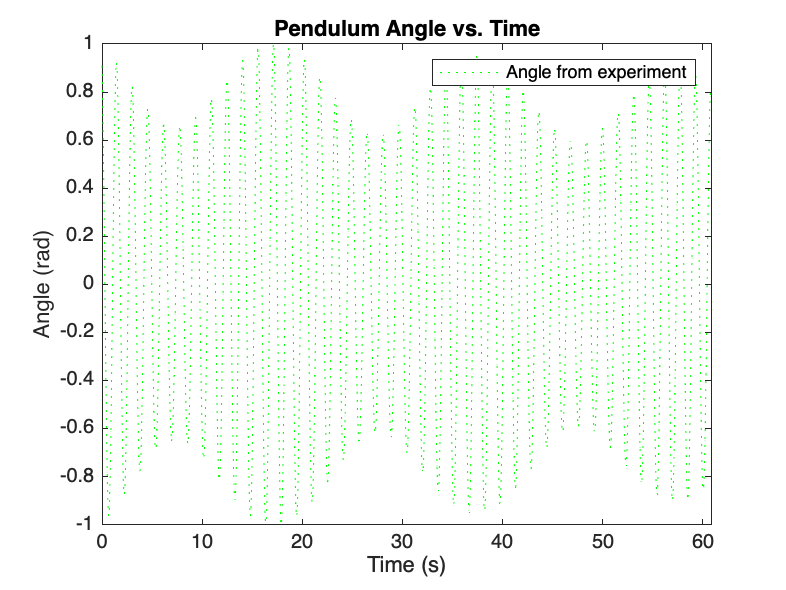

title("Pendulum Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")
% [x,y]=ginput
hold off

plot(fit_for_0_25_same_angle, "fit")
hold on
plot(time_vals, angle_vals_minus_mean,':', "Color", "blue")
title("Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Fit", "Experiment")
ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
xlim([min(time_vals), max(time_vals)])
hold off

ans =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



process_and_plot_pendulum_vals(raw_data.Time_s_0_2SameAngle, raw_data.Angle_ChP1_rad_0_2SameAngle, "20 - Symmetric Oscillation", 3.01)

ans =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


process_and_plot_pendulum_vals(raw_data.Time_s_0_2OppositeAngle, raw_data.Angle_ChP2_rad_0_2OppositeAngle, " 20 - Anti Symmetric Oscillation", 3.01)

% process_and_plot_pendulum_vals(raw_data.Time_s_0_15OppositeAngle , raw_data.Angle_ChP1_rad_0_15OppositeAngle, "15 - Anti Symmetric Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_15SameAnlge, raw_data.Angle_ChP1_rad_0_15SameAnlge, "15 - Symmetric Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_3OppositeAngle, raw_data.Angle_ChP2_rad_0_3OppositeAngle, "30 - Anti Symmetric Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_3SameAngle, raw_data.Angle_ChP2_rad_0_3SameAngle, "30 - Symmetric Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_4OppositeAngle, raw_data.Angle_ChP1_rad_0_4OppositeAngle, "40 - Anti Symmetric Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_4SameAngle, raw_data.Angle_ChP1_rad_0_4SameAngle, "40 - Symmetric Oscillation", 3.01)

[time_vals, angle_vals_minus_mean] = process_and_plot_pendulum_vals(raw_data.Time_s_0_20 , raw_data.Angle_ChP1_rad_0_20, "02 - Oscillation", 3.01)

time_vals =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


angle_vals_minus_mean =     0.5751
    0.5751
    0.5921
    0.5921
    0.5921
    0.6091
    0.6091
    0.6091
    0.6091
    0.6261


hold on 
create_fit_for_single_oscilation_0_2(time_vals, angle_vals_minus_mean, ones(1, length(time_vals)))

ans =      General model Sin2:
     ans(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =         0.5  (fixed at bound)
       b1 =       4.031  (4.031, 4.031)
       c1 =       1.919  (1.908, 1.93)
       a2 =         0.5  (fixed at bound)
       b2 =       4.353  (4.353, 4.354)
       c2 =     0.05282  (0.04218, 0.06346)

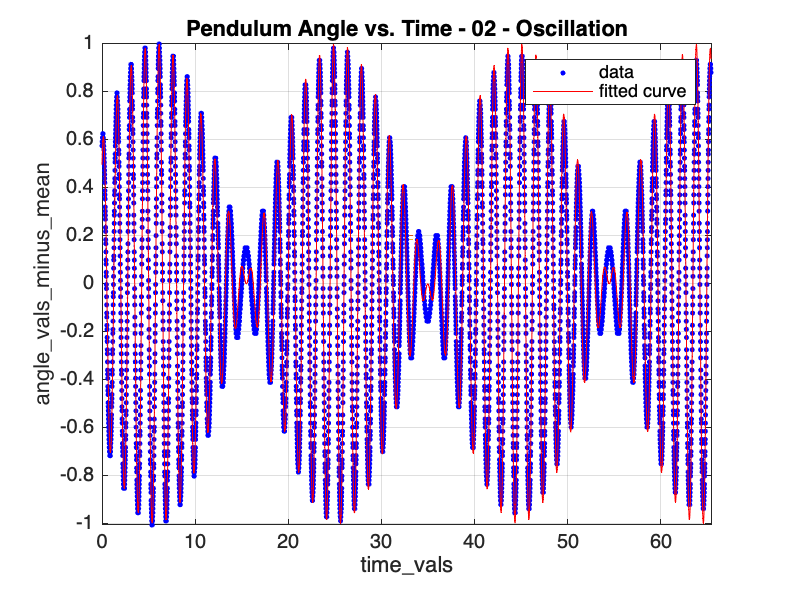

hold off

% process_and_plot_pendulum_vals(raw_data.Time_s_0_15, raw_data.Angle_ChP1_rad_0_15, "15 - Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_35, raw_data.Angle_ChP1_rad_0_35, "30 - Oscillation", 3.01)
% process_and_plot_pendulum_vals(raw_data.Time_s_0_4, raw_data.Angle_ChP1_rad_0_4, "40 - Oscillation", 3.01)


% Plot the omega from fit
calculcated_data = readtable('omega_from_fit.xlsx'); 

heights = rmmissing(calculcated_data.Height_m_);
omega_sym = rmmissing(calculcated_data.OmegaSymetric_1_s_);
omega_anti_sym = rmmissing(calculcated_data.OmegaAntiSymetric_1_s_);
scatter(heights, omega_sym,50 , "Color", "green")
% cftool(heights, omega_sym, [], zeros(1, length(heights)))
hold on 
scatter(heights, omega_anti_sym, 50, "Color", "blue")
hold on
errorbar(heights, omega_anti_sym, 0.001, 0.001, 0.001, 0.001, "yellow");
hold on
errorbar(heights, omega_sym, 0.001, 0.001, 0.001, 0.001, "yellow");
hold on
@(x) ((9.81/(0.58+0.17)+2*3.1/(0.58+0.17)^2/0.16*x^2)^0.5)

ans = function_handle with value:
    @(x)((9.81/(0.58+0.17)+2*3.1/(0.58+0.17)^2/0.16*x^2)^0.5)


arrayfun(@(x) ((9.81/(0.58+0.17)+2*3.1/(0.58+0.17)^2/0.16*x^2)^0.5), [min(heights), max(heights)])

ans =     3.8249    5.1990


fplot(@(x) ((9.81/(0.58+0.17)+2*3.1/(0.58+0.17)^2/0.16*x^2)^0.5), [min(heights), max(heights)])

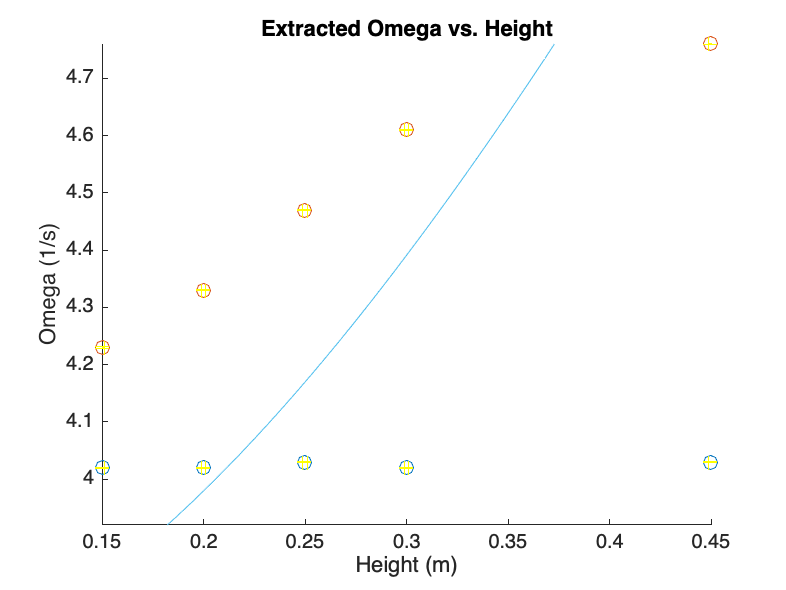

xlim([min(heights), max(heights)])
ylim([min(omega_sym)-0.1, max(omega_anti_sym)])

title("Extracted Omega vs. Height")
xlabel("Height (m)")
ylabel("Omega (1/s)")

% cftool(heights, omega_anti_sym, [], ones(1, length(heights)) * 0.0001)
hold off

function [time_vals, angle_vals_minus_mean] = process_and_plot_pendulum_vals(x_vals, y_vals, input_title, frequency_fit)
    time_vals = rmmissing(x_vals);
    angle_vals = rmmissing(y_vals);
    smallest_input = min(length(time_vals), length(angle_vals));
    time_vals = time_vals(1:smallest_input);
    angle_vals = angle_vals(1:smallest_input);
    angle_vals_minus_mean = (angle_vals - mean(angle_vals));
    angle_vals_minus_mean = angle_vals_minus_mean ./ max(angle_vals_minus_mean);
    plot(time_vals, angle_vals_minus_mean,':', "Color", "blue")
    hold on 
    errorbar(time_vals(smallest_input/2:smallest_input/2+1,1:1), angle_vals_minus_mean(smallest_input/2:smallest_input/2+1,1:1), 0.001, 0.001, 0.001, 0.001);
    hold on
    % fplot(@(x) 0.1*sin(frequency_fit*x - 1.2) - 0.2, [min(time_vals), max(time_vals)])
    title(strcat("Pendulum Angle vs. Time - ", input_title))
    xlabel("Time (s)")
    ylabel("Angle (rad)")
    ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
    xlim([min(time_vals), max(time_vals)])

    % cftool(time_vals, angle_vals_minus_mean, [], ones(1, length(time_vals)) * 0.0001)
    hold off
end
